srcDir = "..\srcImages\";

barbara = readraw(srcDir + "barbara.raw");

    "→Retrieving Image "    "..\srcImages\barbara.raw"    " ..."



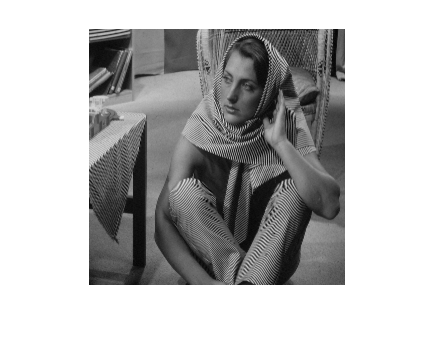

imshow(barbara);

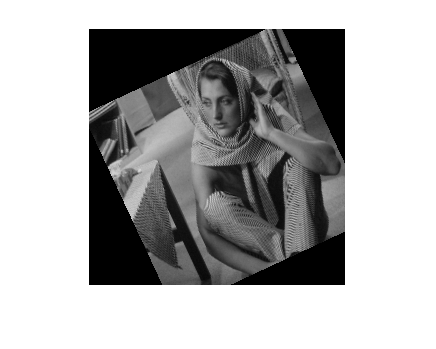


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 5);
imshow(affectedBarbara);

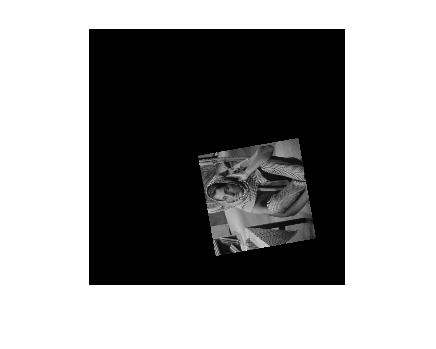


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 20);
imshow(affectedBarbara);

baboon = readraw(srcDir + "baboon.raw");

    "→Retrieving Image "    "..\srcImages\baboon.raw"    " ..."



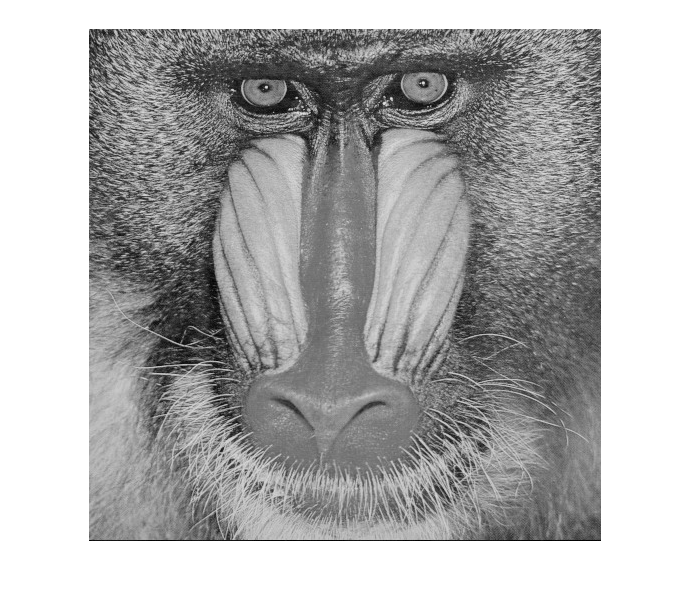

imshow(baboon);

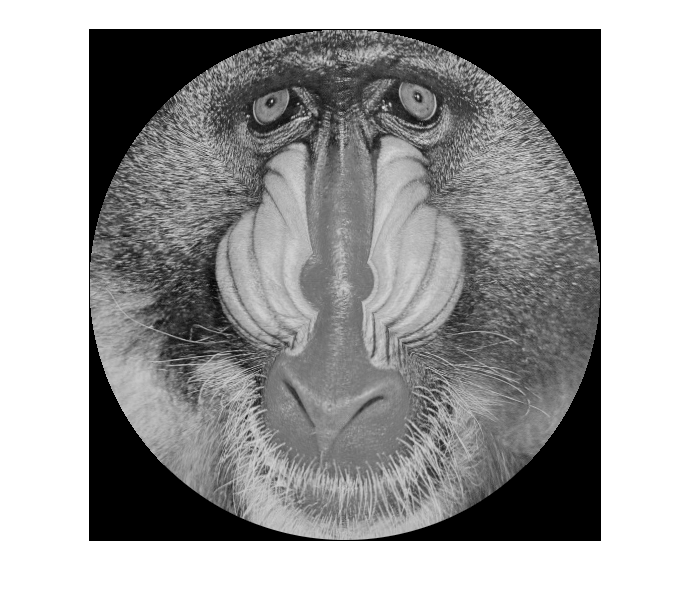


diskBaboon = toDisk(baboon);
imshow(diskBaboon);

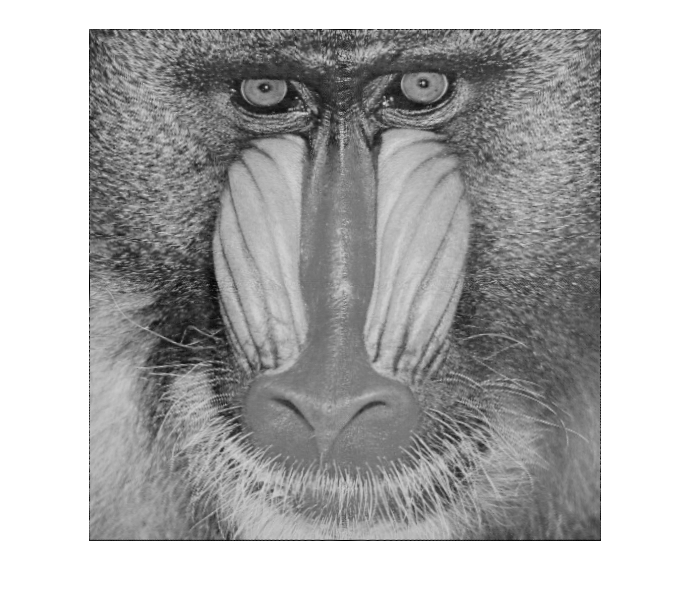


resquaredBaboon = fromDisk(diskBaboon);
imshow(resquaredBaboon);

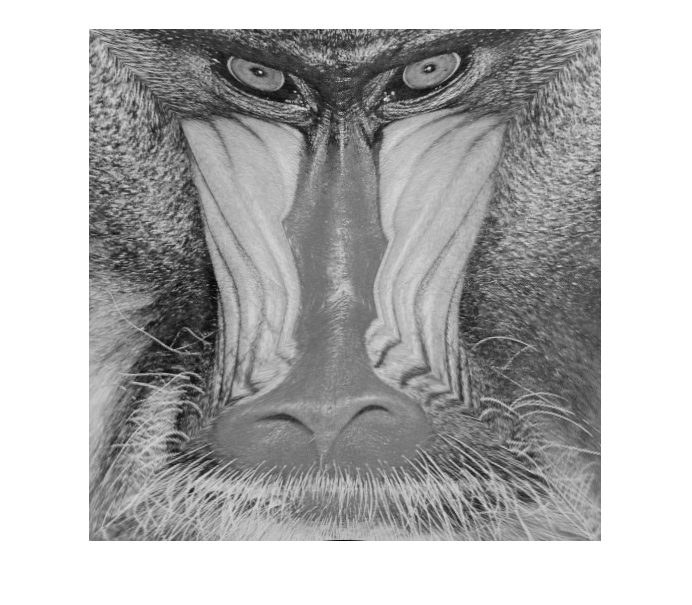


%diskBaboon = warp(barbara, inverseDisk(128.5));
%imshow(diskBaboon);

%resquaredBaboon = fromDisk(baboon);
%imshow(resquaredBaboon);

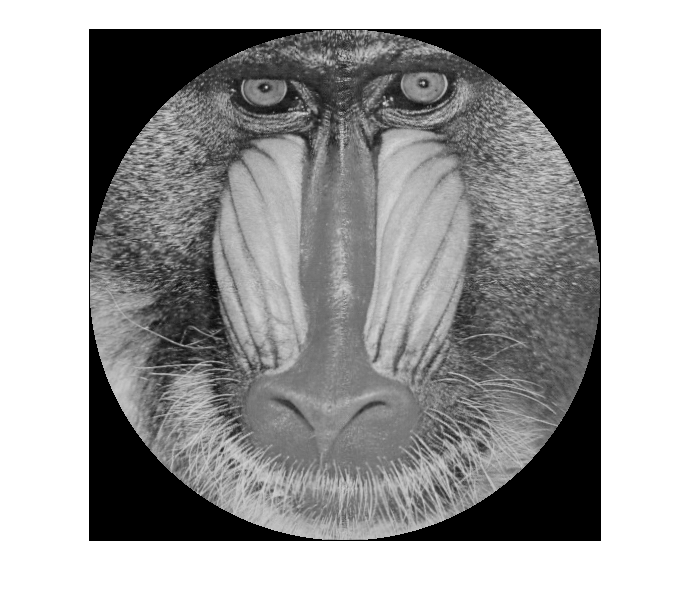

%imshow(toDisk(resquaredBaboon));

    "→Retrieving Image "    "..\srcImages\sample1.raw"    " ..."



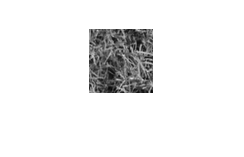

    "→Retrieving Image "    "..\srcImages\sample2.raw"    " ..."



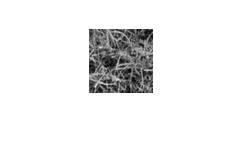

    "→Retrieving Image "    "..\srcImages\sample3.raw"    " ..."



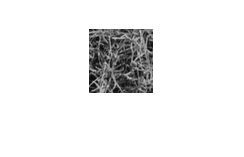

    "→Retrieving Image "    "..\srcImages\sample4.raw"    " ..."



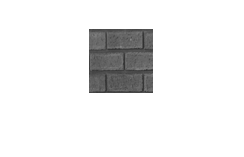

    "→Retrieving Image "    "..\srcImages\sample5.raw"    " ..."



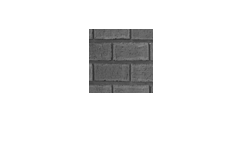

    "→Retrieving Image "    "..\srcImages\sample6.raw"    " ..."



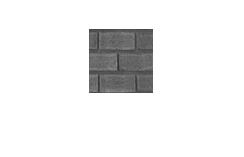

    "→Retrieving Image "    "..\srcImages\sample7.raw"    " ..."



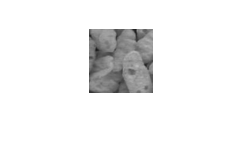

    "→Retrieving Image "    "..\srcImages\sample8.raw"    " ..."



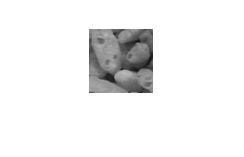

    "→Retrieving Image "    "..\srcImages\sample9.raw"    " ..."



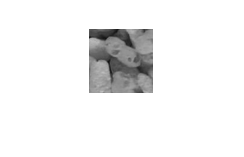

    "→Retrieving Image "    "..\srcImages\sample10.raw"    " ..."



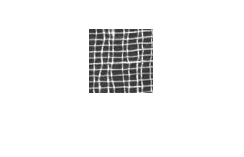

    "→Retrieving Image "    "..\srcImages\sample11.raw"    " ..."



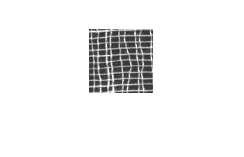

    "→Retrieving Image "    "..\srcImages\sample12.raw"    " ..."



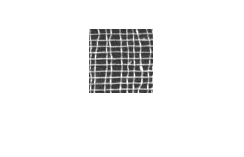

    "→Retrieving Image "    "..\srcImages\sample13.raw"    " ..."



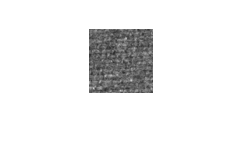

    "→Retrieving Image "    "..\srcImages\sample14.raw"    " ..."



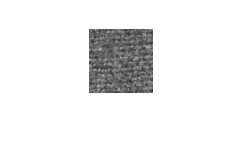

    "→Retrieving Image "    "..\srcImages\sample15.raw"    " ..."



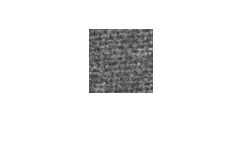

txClasses = zeros(64, 64, 15);

for i = 1:15
    txClasses(:, :, i) = readraw(srcDir + "sample" + string(i) + ".raw");
end

    "→Retrieving Image "    "..\srcImages\sample1.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample2.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample3.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample4.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample5.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample6.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample7.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample8.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample9.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample10.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample11.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample12.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample13.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample14.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample15.raw"    " ..."




classes = classifyLawsSmallTextures(txClasses, 5);

   13.1021   12.7394   12.1354   11.9245   13.5513   14.0304   10.2839   11.7732   12.6731
   14.4226   13.3391   13.1195   13.7797   15.1471   15.9870   11.7955   13.5703   15.0357
   14.5609   13.8925   13.5348   13.3825   15.6913   15.9278   11.2719   14.1521   15.1511
    5.0341    4.1278    4.4174    4.6943    2.8426    3.5241    4.4144    3.2188    4.2390
    5.1180    4.7154    5.1121    4.8898    3.0295    3.6603    4.5098    3.4463    4.3840
    4.7153    4.1677    4.6139    4.4410    2.7471    3.3651    3.9834    3.1038    3.9368
   10.6488    5.5005    3.1150    4.9768    3.8022    2.8811    2.9401    2.7577    2.4084
   14.8721    5.4225    2.8429    7.0221    4.3987    3.1543    4.0065    3.3491    2.8426
   15.1600    5.7899    3.2313    6.5699    4.2217    3.0361    3.6767    3.2324    2.7006
   17.0828   20.9206   21.9766   21.6660    9.9631   11.7864   22.4996   10.5520   10.4143
   17.4233   21.1645   22.0057   21.2249   10.7932   13.2260   22.1029   10.0683   10.6866

     4
     4
     4
     3
     3
     3
     5
     5
     5
     1
     1
     1
     2
     2
     2



mosaic1 = readraw(srcDir + "comb1.raw");

    "→Retrieving Image "    "..\srcImages\comb1.raw"    " ..."



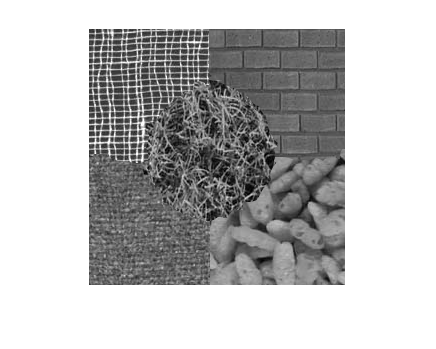

imshow(mosaic1);

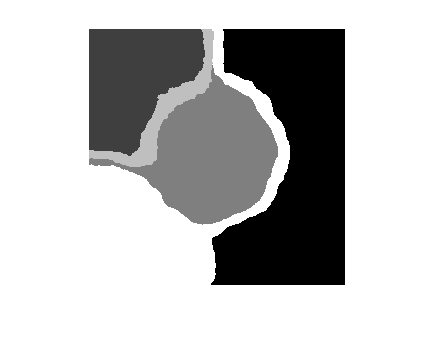

segmented1 = segmentTextures(mosaic1, [0, 63, 127, 191, 255]);
imshow(segmented1);


mosaic2 = readraw(srcDir + "comb2.raw");

    "→Retrieving Image "    "..\srcImages\comb2.raw"    " ..."



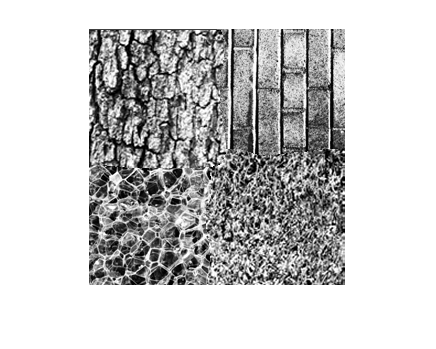

imshow(mosaic2);

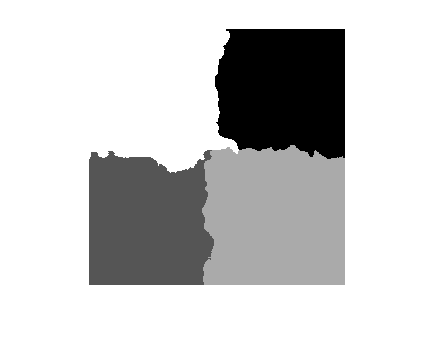

segmented2 = segmentTextures(mosaic2, [0, 85, 170, 255]);
imshow(segmented2);

colors = [0, 85, 170, 255];
connectedParts = connectedComponents(segmented2);
frequencyList = frequencies(connectedParts);
keptComponents = largestComponents(segmented2, connectedParts, [0, 85, 170, 255], frequencyList);

keptComponents =     51    73     2     6


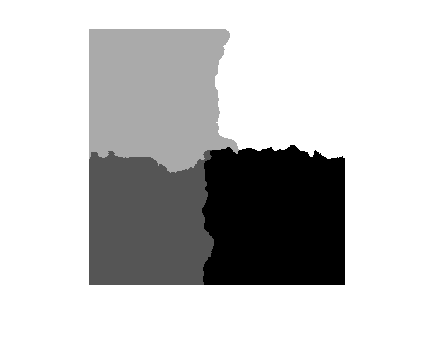

segmented = mergeComponents(connectedParts, frequencyList, keptComponents);
[rows, cols] = size(connectedParts);
for row = 1:rows
    for col = 1:cols
        for i = 1:4
            if segmented(row, col) == keptComponents(i)
                segmented(row, col) = colors(i);
            end
        end
    end
end
imshow(uint8(segmented));